# Given Variables

At = 50e-4;         % 50 cm^2 = 0.005 m^2
Aout = 25e-6;       % 25 mm^2 = 0.000025 m^2
zeta = 0.05;
rho = 1000;         % 1000 kg/m^3
g = 9.81;           % 9.81 m/s^2
hmax = 0.3;         % 0.3 m
umax = 5;           % 5 V

# Compute b

b = 1/(rho*At)

b = 0.2000

Measure for a1 and a2

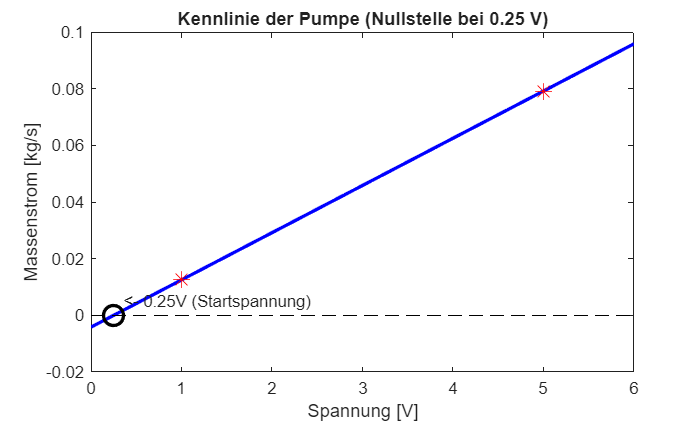

input_v = [1 5];
mass_flow = [750 4750]* (0.001 / 60);
p = polyfit(input_v, mass_flow, 1); 
x_range = 0:0.1:6; 
y_values = polyval(p, x_range);
figure;
plot(x_range, y_values, 'b-', 'LineWidth', 2); hold on;
plot(input_v, mass_flow, 'r*', 'MarkerSize', 10); % Die Original-Messpunkte
plot([0 6], [0 0], 'k--'); % X-Achse (Nulllinie Flow)
xlabel('Spannung [V]');
ylabel('Massenstrom [kg/s]');
title(['Kennlinie der Pumpe (Nullstelle bei ' num2str(-p(2)/p(1)) ' V)']);
plot(0.25, 0, 'ko', 'MarkerSize', 12, 'LineWidth', 2);
text(0.25, 0.005, '  <- 0.25V (Startspannung)', 'FontSize', 10);

k_pump = (mass_flow(2) - mass_flow(1)) / (input_v(2) - input_v(1))

k_pump = 0.0167

y_intercept = mass_flow(1) - k_pump * input_v(1); % Das ist dein bisheriges v0 (Y-Achsenabschnitt)
v0 = -y_intercept / k_pump

v0 = 0.2500

# Calibration to convert Sensor output voltage to height2

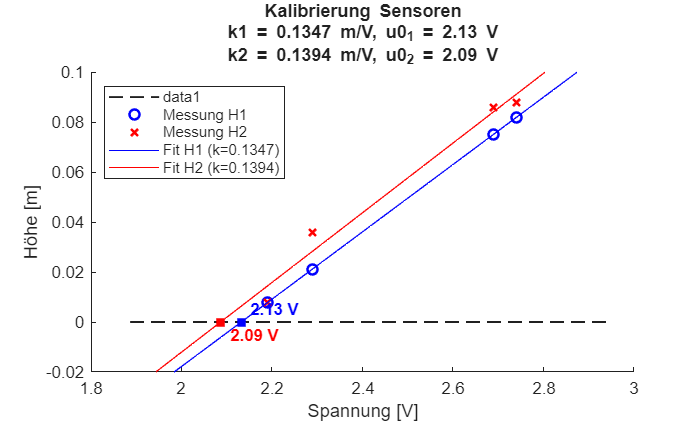

meas_input_v =   [2    3     4    5];
meas_output_v2 = [2.19 2.29 2.69   2.74 ];

% Daten in Meter umrechnen
meas_height1 =   [0.8 2.1    7.5    8.2] / 100;
meas_height2 =   [0.8 3.6    8.6    8.8] / 100;

% 1. Lineare Regression (Height = k * Voltage + d)
p1 = polyfit(meas_output_v2, meas_height1, 1);
p2 = polyfit(meas_output_v2, meas_height2, 1);

% Parameter extrahieren
k1 = p1(1);% Steigung (Slope)
d1 = p1(2); % OffsetVS"
k2 = p2(1); % Steigung (Slope)
d2 = p2(2); % Offset

% 2. Nullstellen berechnen (Spannung bei Höhe = 0)
% 0 = k*x + d  =>  x = -d/k
u0_1 = -d1 / k1;
u0_2 = -d2 / k2;

% --- Plotting ---
figure;
hold on;

% Plot-Bereich definieren
x_start = min([u0_1, u0_2]) - 0.2; 
x_end = max(meas_output_v2) + 0.2;
x_range = linspace(x_start, x_end, 100);

% Nulllinie (X-Achse) korrekt einzeichnen
line([x_start x_end], [0 0], 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1);

% Messpunkte plotten
plot(meas_output_v2, meas_height1, 'bo', 'LineWidth', 1.5, 'DisplayName', 'Messung H1');
plot(meas_output_v2, meas_height2, 'rx', 'LineWidth', 1.5, 'DisplayName', 'Messung H2');

% Ausgleichsgeraden plotten
plot(x_range, polyval(p1, x_range), 'b-', 'DisplayName', sprintf('Fit H1 (k=%.4f)', k1));
plot(x_range, polyval(p2, x_range), 'r-', 'DisplayName', sprintf('Fit H2 (k=%.4f)', k2));

% Nullstellen markieren und beschriften
plot(u0_1, 0, 'bs', 'MarkerFaceColor', 'b', 'HandleVisibility', 'off');
text(u0_1, 0.005, sprintf('  %.2f V', u0_1), 'Color', 'b', 'FontWeight', 'bold');

plot(u0_2, 0, 'rs', 'MarkerFaceColor', 'r', 'HandleVisibility', 'off');
text(u0_2, -0.005, sprintf('  %.2f V', u0_2), 'Color', 'r', 'FontWeight', 'bold');

xlabel('Spannung [V]');
ylabel('Höhe [m]');
title({ 'Kalibrierung Sensoren', ...
        sprintf('k1 = %.4f m/V, u0_1 = %.2f V', k1, u0_1), ...
        sprintf('k2 = %.4f m/V, u0_2 = %.2f V', k2, u0_2) });
legend('Location', 'northwest');
ylim([-0.02 0.1]); 

fprintf('Ergebnisse:\n');

Ergebnisse:


fprintf('Sensor 1: k = %.4f m/V,  u0 = %.4f V\n', k1, u0_1);

Sensor 1: k = 0.1347 m/V,  u0 = 2.1322 V


fprintf('Sensor 2: k = %.4f m/V,  u0 = %.4f V\n', k2, u0_2);

Sensor 2: k = 0.1394 m/V,  u0 = 2.0866 V


a1_vec = (b * k_pump * (meas_input_v - v0)) ./ sqrt(meas_height1);
a2_vec = a1_vec .* (sqrt(meas_height1) ./ sqrt(meas_height2));

a1_final = mean(a1_vec)

a1_final = 0.0574

a2_final = mean(a2_vec)

a2_final = 0.0524